# The Spotify Effect

Acevedo, Contreras & Razmilic

### Basic Model: no horizontal selection

## Parameter Setup

%% Solve the basic model equilibrium with lsqnonlin
clear; clc;

rng(1);
n = 2;
sigma   = 2;                  % Elasticity of substitution (sigma > 1)
alpha   = ones(n,1)./n;       % Occupation weight vector (n x 1)
delta_1 = 0.5;                % Productivity parameter intercept
delta_2 = 1;                  % Productivity parameter slope
gamma_1 = 0.5;                % Taste parameter intercept
gamma_2 = 1;                  % Taste parameter slope
tau_base = [0; 0]';             % Barrier (technological cost) for each occupation
tau_slope = [0; 2]';             % Barrier (technological cost) for each occupation

theta   = 1.5;                % Frechet shape parameter

%% Create a grid for Q from a standard normal and shift it to be positive
N_grid = 1000;                         % Number of grid points
Q_grid = randn(N_grid, 1);              % Draw Q from standard normal
Q = sort(Q_grid);                       % Sort the grid
w = normpdf(Q) ./ sum(normpdf(Q));       % Use the analytic normal density (normalized)

%% Set up the unknown vector x
% Unknowns: prices (p) for each occupation (n x 1) and final aggregated output y (scalar)
p0 = ones(n,1);  % Initial guess for prices
y0 = 1;          % Initial guess for final output
x0 = [p0; y0];

%% Set options for lsqnonlin
options_lsq = optimoptions('lsqnonlin', 'Display', 'iter', 'TolFun', 1e-8, 'TolX', 1e-8);

%% Call lsqnonlin to solve the equilibrium equations
sol = lsqnonlin(@(x) tse_basic_model(sigma, alpha, x, Q, w, delta_1, delta_2, gamma_1, gamma_2, tau_base, tau_slope, theta), x0, [], [], options_lsq);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4          0.528929                            0.477
     1          8          0.404204        0.737575             3.03      
     2         12         0.0413577        0.184394            0.377      
     3         16         0.0256341        0.115227          0.00374      
     4         20         0.0255656       0.0253881         0.000703      
     5         24         0.0255637      0.00406542         0.000163      
     6         28         0.0255636     0.000663986         2.86e-05      
     7         32         0.0255636     0.000111168         4.84e-06      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the 


%% Extract solution components
p = sol(1:n);  % Equilibrium prices (n x 1)
y = sol(n+1);  % Equilibrium final output (scalar)

fprintf('Equilibrium Prices (p):\n');

Equilibrium Prices (p):


disp(p);

    0.8199
    1.7433



fprintf('Equilibrium Final Output (y):\n');

Equilibrium Final Output (y):


disp(y);

    1.3990



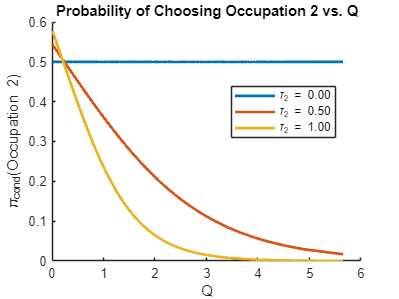

%% Iterating over tau2, solving equilibrium, and plotting quality in Occupation 2
clear; clc

% ------------------
% Model Parameters
% ------------------
n         = 2;       % number of occupations
sigma     = 2;       % elasticity of substitution (>1)
alpha     = ones(n,1)./n;
delta_1   = 0.5;
delta_2   = 1;
gamma_1   = 0.5;
gamma_2   = 1;
tau1_fixed= 0;       % fixed barrier for occupation 1
theta     = 1.5;     % Frechet shape parameter

tau_base = [0; 0];             % Barrier (technological cost) for each occupation
tau_slope = [0; 2];             % Barrier (technological cost) for each occupation

% -------------
% Q and Weights
% -------------
N_grid = 200;                          % number of grid points
Q_grid = sort(randn(N_grid,1));        % standard normal sample, sorted
Q_grid = Q_grid - min(Q_grid) + 0.01;  % shift so Q>0
w = normpdf(Q_grid);                   % standard normal pdf
w = w ./ sum(w);                       % normalize

% -------------------------------
% Range of tau2 values to explore
% -------------------------------
tau2_slope_values = linspace(0,1,3);  % 6 equally spaced values of tau2
colors = lines(length(tau2_slope_values));

% We'll also store the average quality for each tau2
avg_quality_2 = zeros(size(tau2_slope_values));

% Create a figure for the probability-of-occupation-2 curves
figure('Name','Probability of Choosing Occupation 2','Color','w');
hold on;

for i = 1:length(tau2_slope_values)
    tau_current = [tau1_fixed; tau2_slope_values(i)];
    
    % Solve for equilibrium (p,y) with lsqnonlin
    p0 = ones(n,1); 
    y0 = 1;
    x0 = [p0; y0];
    options_lsq = optimoptions('lsqnonlin','Display','off','TolFun',1e-8,'TolX',1e-8);
    sol = lsqnonlin(@(x) tse_basic_model(sigma, alpha, x, Q_grid, w, ...
                                         delta_1, delta_2, gamma_1, gamma_2, ...
                                         tau_base, tau_current, theta), ...
                    x0, [], [], options_lsq);

    % Equilibrium solution
    p_sol = sol(1:n);
    y_sol = sol(n+1);

    % a(Q), b(Q)
    a_vals = delta_1 + delta_2.*Q_grid;  
    b_vals = gamma_1 + gamma_2.*Q_grid;
    tau = tau_base + tau_current.*Q_grid';

    % Base utility (n x N_grid)
    u_no_sel = exp(-tau) .* p_sol .* ((a_vals .* b_vals)');

    % Conditional probabilities (n x N_grid)
    denom   = sum(u_no_sel.^theta, 1);
    pi_cond = (u_no_sel.^theta) ./ denom;

    % --- Vector of quality for Occupation 2 ---
    % quality_2(q) = a(q) * [ pi_cond(2,q) ]^((theta-1)/theta)
    curve_2 = a_vals .* (pi_cond(2,:)'.^((theta-1)/theta));  % (N_grid x 1)

    % Compute the average (a single scalar) for later use
    avg_quality_2(i) = sum(curve_2 .* w);  

    % pi_cond(2,:) is a 1 x N_grid row; let's plot it vs. Q_grid
    plot(Q_grid, pi_cond(2,:), 'Color', colors(i,:), 'LineWidth', 2, ...
        'DisplayName', sprintf('\\tau_2 = %.2f', tau2_slope_values(i)));
end

% finalize probability figure
xlabel('Q');
ylabel('\pi_{cond}(Occupation 2)');
title('Probability of Choosing Occupation 2 vs. Q');
legend('Location','best');
hold off;

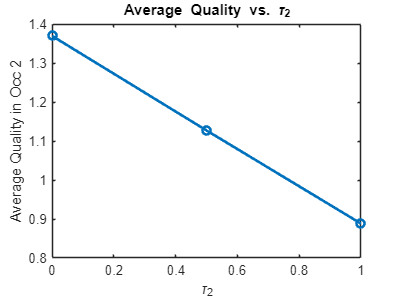


% 2) Plot the average quality vs. tau2 in a separate figure
figure('Name','Average Quality Occupation 2','Color','w');
plot(tau2_slope_values, avg_quality_2,'-o','LineWidth',2);
xlabel('\tau_2');
ylabel('Average Quality in Occ 2');
title('Average Quality vs. \tau_2');
grid off;

### Functions

function Eq = tse_basic_model(sigma, alpha, x, Q, w, delta_1, delta_2, gamma_1, gamma_2, tau_base, tau_slope, theta)
    % Number of occupations and grid points:
    n = length(alpha);
    
    % The unknown vector x contains only prices:
    p = x(1:n);  % (n x 1)
    y = x(n+1);

    Q = Q - min(Q)+0.01;   % Shift so that mini
    % mum is 0.01 (all Q positive)

    % Compute productivity and taste parameters on the Q grid:
    a = delta_1 + delta_2 .* Q;  % (m x 1)
    b = gamma_1 + gamma_2 .* Q;  % (m x 1)
    tau = tau_base + tau_slope.*Q';

    % Compute the base utility without selection effects for each occupation and Q:
    % Dimensions: p is (n x 1), (a.*b)' is (1 x m) so that u_no_selection is (n x m)
    u_no_selection = exp(-tau) .* p .* ( (a .* b)' );
    
    % For each grid point j, compute the conditional occupation probability:
    %   pi_cond(i,j) = [u_no_selection(i,j)]^theta / sum_{i=1}^n [u_no_selection(i,j)]^theta.
    denom = sum(u_no_selection.^theta, 1);          % 1 x m
    pi_cond = (u_no_selection.^theta) ./ repmat(denom, n, 1);  % n x m
    
    % Aggregate occupation share for each occupation:
    %   Pi(i) = \int pi_cond(i,Q) dF(Q) approximated as sum_j w(j)*pi_cond(i,j)
    Pi = sum(pi_cond .* repmat(w', n, 1), 2);  % n x 1
    
    % Production in each occupation (y):
    %   y(i) = sum_j [ w(j) * a(j) * (pi_cond(i,j))^((theta-1)/theta) ]
    y_x = sum(w.*a.*(pi_cond'.^((theta-1)./theta)));
    
    % Final aggregated output:
    final_output = sum(alpha .* (y_x').^((sigma-1)/sigma)).^(sigma/(sigma-1));
    
    % Equilibrium Conditions:
    % 1. Numeraire condition: final good price is normalized to 1.
    Eq1 = 1 - (sum(alpha .* p.^(1-sigma)))^(1./(1-sigma));
    
    % 2. Market clearing for each occupation:
    %    The computed aggregate share Pi(i) must equal alpha(i)*final_output*p(i)^(-sigma)
    Eq2 = Pi.^((theta-1)./theta) - alpha .* y .* p.^(-sigma);   % (n x 1)
    
    % 3. Occupation shares must sum to 1:
    Eq3 = sum(Pi) - 1;
        
    Eq4 = y - final_output;

    Eq5 = sum(Pi) - 1;
    % Combine equilibrium conditions into one vector:
    Eq = [Eq1; Eq2; Eq3; Eq4; Eq5];


end
